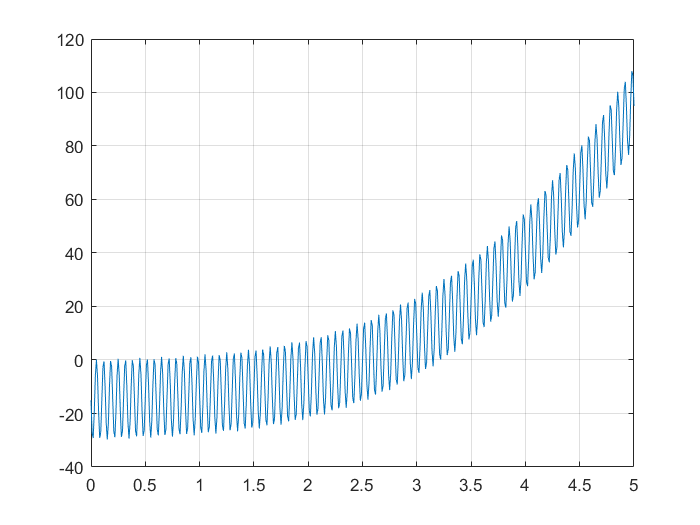

clear
clc
y = dlmread('f11.txt');
dt = 0.01;
T = 5;
t = 0:dt:T;

plot(t,y),grid;

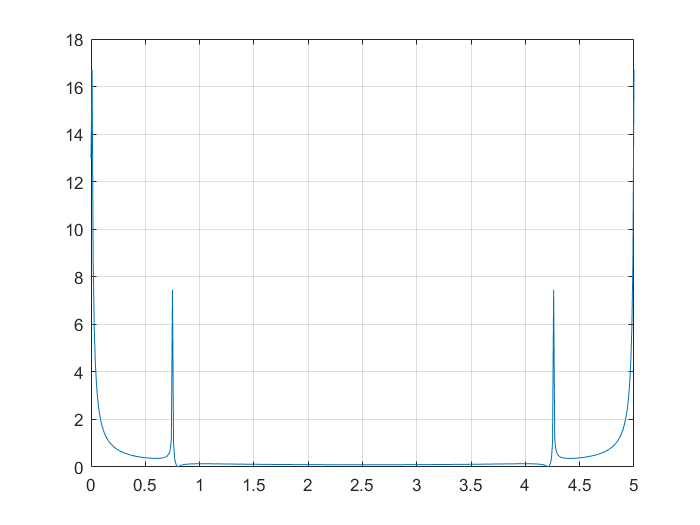

%using standart FFT for comparison purpose
f = fft(y);

n = length(y);
%declaring structures
c1(1:n) = 0;
c2(1:n) = 0;
c(1:n) = 0;

%my FFT
for k = 1:n
    cos_sum = 0;
    sin_sum = 0;
    for  m = 1:n
        cos_sum = cos_sum + y(m)*cos(2*pi*(k-1)*(m-1)/n);
        sin_sum = sin_sum + y(m)*sin(2*pi*(k-1)*(m-1)/n); 
    end
    c1(k) = cos_sum/n;
    c2(k) = sin_sum/n;
    c(k) = sqrt(c1(k)*c1(k)+c2(k)*c2(k));
end

%mine
figure;
plot(t,c),grid;

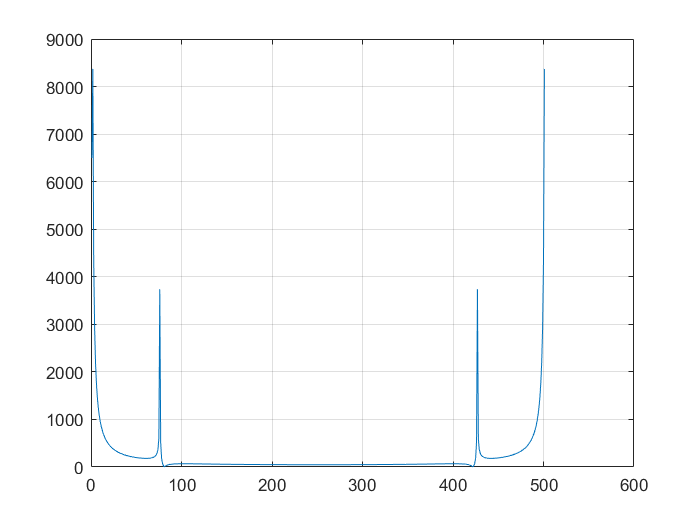


%standart
figure;
plot(abs(f)),grid;


k=0;

for i=3:(n/2 - 2)
    if((c(i-1)<c(i))&(c(i+1)<c(i))&(c(i-2)<c(i))&(c(i+2)<c(i))) 
            k = k+1;
            max(k) = i;
    end
end
w = (max-1)/T;
w

w =    15.0000   20.4000


max

max =     76   103




b(1) = 0;
for i= 1: n
    b(1) = b(1) + y(i)*t(i)*t(i)*t(i);
end

b(2) = 0;
for i= 1: n
    b(2) = b(2) + y(i)*t(i)*t(i);
end

b(3) = 0;
for i= 1: n
    b(3) = b(3) + y(i)*t(i);
end

b(4) = 0;
for i= 1: n
    b(4) = b(4) + y(i)*sin(2*pi*w(1)*t(i));
end

b(5) = 0;
for i= 1: n
    b(5) = b(5) + y(i)*sin(2*pi*w(2)*t(i));
end

b(6) = 0;
for i= 1: n
    b(6) = b(6) + y(i);
end

b

b = 	1.0e+05 *

    7.5407    1.6822    0.3677   -0.0386   -0.0007    0.0650



a(1,1)=sum(t.^6);
a(1,2)=sum(t.^5);
a(1,3)=sum(t.^4);
a(1,4)=sum(sin(2*pi*w(1).*t).*t.^3);
a(1,5)=sum(sin(2*pi*w(2).*t).*t.^3);
a(1,6)=sum(t.^3);


a(2,1)=sum(t.^5);
a(2,2)=sum(t.^4);
a(2,3)=sum(t.^3);
a(2,4)=sum(sin(2*pi*w(1).*t).*t.^2);
a(2,5)=sum(sin(2*pi*w(2).*t).*t.^2);
a(2,6)=sum(t.^2);

a(3,1)=sum(t.^4);
a(3,2)=sum(t.^3);
a(3,3)=sum(t.^2);
a(3,4)=sum(sin(2*pi*w(1).*t).*t);
a(3,5)=sum(sin(2*pi*w(2).*t).*t);
a(3,6)=sum(t);

a(4,1)=sum(t.^3.*sin(2*pi*w(1).*t));
a(4,2)=sum(t.^2.*sin(2*pi*w(1).*t));
a(4,3)=sum(t.*sin(2*pi*w(1).*t));
a(4,4)=sum(sin(2*pi*w(1).*t).*sin(2*pi*w(1).*t));
a(4,5)=sum(sin(2*pi*w(1).*t).*sin(2*pi*w(2).*t));
a(4,6)=501*sum(sin(2*pi*w(1).*t));

a(5,1)=sum(t.^3.*sin(2*pi*w(2).*t));
a(5,2)=sum(t.^2.*sin(2*pi*w(2).*t));
a(5,3)=sum(t.*sin(2*pi*w(2).*t));
a(5,4)=sum(sin(2*pi*w(2).*t).*sin(2*pi*w(1).*t));
a(5,5)=sum(sin(2*pi*w(2).*t).*sin(2*pi*w(2).*t));
a(5,6)=501*sum(sin(2*pi*w(2).*t));

a(6,1)=sum(t.^3);
a(6,2)=sum(t.^2);
a(6,3)=sum(t);
a(6,4)=sum(sin(2*pi*w(1).*t));
a(6,5)=sum(sin(2*pi*w(2).*t));
a(6,6)=501;

x=inv(a)*b'

x =     1.0000
   -1.0000
    2.0000
  -15.0000
   -0.0000
  -15.0000


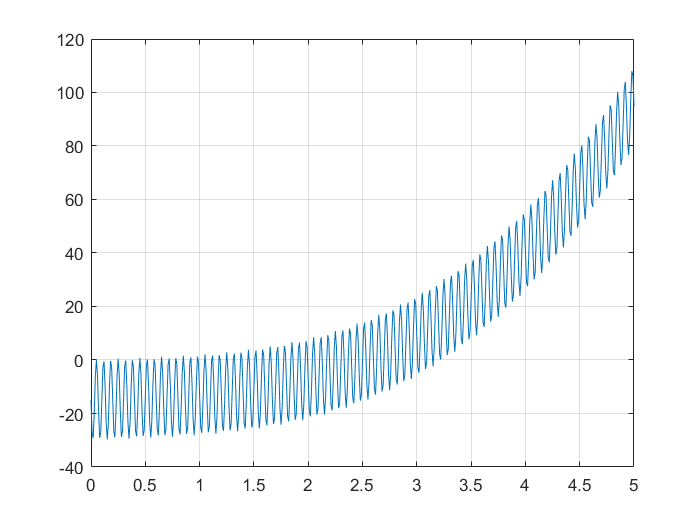


approximation = x(1).*t.^3+x(2).*t.^2+x(3).*t+x(4)*sin(2*pi*w(1).*t)+x(5)*sin(2*pi*w(2).*t)+x(6);
figure;
plot(t,approximation),grid;

err = 0;
for i = 1:n 
    err = err + (approximation(i)-y(i))*(approximation(i)-y(i));
end;
err

err = 3.3865e-07